# ปัญหาวันที่ 2

## เป้าหมาย

- สามารถระบุตำแหน่งของ stamping event ได้

- สามารถจำแนก stamping event ได้ (N/F)

- สามารถอธิบายแนวทางในการหาตำแหน่ง event การตัด segment และการจำแนก event ได้

## ข้อกำหนด

- ใช้ไฟล์ที่อยู่ใน folder Day2 ในการ train model โดยต้องตัดเองและเลือกความยาวในการตัดเอง

## ผลลัพธ์ที่ต้องการ

- โปรแกรมจะอ่านไฟล์ที่กำหนด แล้วแสดงผลลัพธ์เป็นตำแหน่งของ event และสถานะเป็น N (normal) หรือ F (faulty) บรรทัดละ event

- ตำแหน่งของ event จะเป็นลำดับของ sample นับตั้งแต่พบสัญญาณ SYNC โดยอนุญาตให้คลาดเคลื่อนได้ +/- 14400 sample (0.3 วินาที)

- รูปแบบการแสดงผลคล้ายดังนี้

102230 N

197740 F

275941 F

...

## โครงโปรแกรม

สามารถเขียนใหม่ได้ทั้งหมด ไม่จำเป็นต้องใช้ตามนี้

ตอนตรวจขั้นสุดท้าย จะต้องเปลี่ยนชื่อไฟล์ด้านล่างนี้ให้เป็นไฟล์ที่กำหนด

[audioData, Fs] = audioread('Day2/Normal1.wav');

shortWinLength = round(0.3 * Fs);
longWinLength = round(2.0 * Fs);

shortRMS = dsp.MovingRMS(shortWinLength);
longRMS = dsp.MovingRMS(longWinLength);

env1 = shortRMS(audioData);
env2 = longRMS(audioData);

shortOffset = round(shortWinLength/2);
longOffset = round(longWinLength/2);

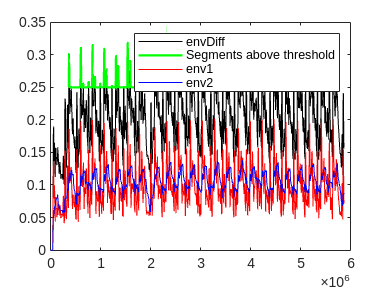

envDiff = env1 + env2;

% Set the constant k and threshold
k = 1;
threshold = k * mean(envDiff) + std(envDiff);

% Find indices where envDiff is greater than the threshold
segments = envDiff > threshold;
segmentIndices = find(segments);  % Get sample numbers (indices) where envDiff > threshold

% Plot the original envDiff
plot(envDiff, 'k');
hold on;

% Plot the segments above the threshold in a different color
plot(segmentIndices, envDiff(segments), 'g', 'LineWidth', 1.5);
    
% Plot env1 and env2 for reference
plot(env1, 'r');
plot(env2, 'b');

hold off;
legend('envDiff', 'Segments above threshold', 'env1', 'env2');


segmentRanges = [];  % To store start and end of each segment

% Loop through the segmentIndices and find continuous ranges
if ~isempty(segmentIndices)
    startIdx = segmentIndices(1);  % Start of the first segment

    for i = 2:length(segmentIndices)
        % Check if the current index is not consecutive to the previous one
        if segmentIndices(i) ~= segmentIndices(i-1) + 1
            % End of the current segment
            endIdx = segmentIndices(i-1);
            segmentRanges = [segmentRanges; startIdx, endIdx];  % Store the range
            startIdx = segmentIndices(i);  % Start a new segment
        end
    end
    
    % Add the last segment
    segmentRanges = [segmentRanges; startIdx, segmentIndices(end)];
end

% Display segment ranges
disp('Segment Ranges:');

Segment Ranges:


disp(segmentRanges);

      363167      378716
      413779      414513
      596747      613057
      655254      657625
      755541      765420
      831061      847859
      847866      847869
      879661      879661
      879663      894246
      989661      999207
     1065410     1081917
     1081922     1081932
     1112883     1112929
     1112967     1112978
     1112980     1112987
     1113060     1113065
     1113073     1130683
     1226016     1226016
     1226019     1226019
     1226024     1233423
     1301019     1315680
     1347029     1361732
     1465574     1465592
     1465597     1465599
     1465651     1465665
     1465667     1467521
     1534090     1551993
     1581598     1599897
     1695352     1704758
     1772027     1787066
     1819269     1833148
     1833269     1833271
     1833274     1836222
     2079904     2097521
     2097537     2097542
     2097546     2097553
     2097556     2097563
     2097565     2097565
     2131390     2140597
     2316402     2334136


size_file = size(locs1);
for i = 1:size_file(1)

        filename = sprintf("Train/Faulty/Faulty%d.wav", 52 + i);  % Use %d to insert the loop index
        % Write the audio data to the WAV file
        audiowrite(filename, audioData(locs1(i) - 1.2e4:locs2(i)), Fs);
end


player = audioplayer(audioData(segmentIndices), Fs); % must specify correct sampling rate
play(player);

stop(player)